scale = 9.9/7;
ff = 5;
R = 8.01*(scale)  %mm

R = 11.3284

alpha = deg2rad(27.5) %input in deg

alpha = 0.4800

beta = alpha   %input in deg

beta = 0.4800

C = 6*(scale)

C = 8.4857

H = 45.86*(scale)

H = 64.8591

b = 13.7*(scale)

b = 19.3757

a = 13*(scale) %found by reducing or increasing such that gammamax - gammamin = alpha + beta

a = 18.3857

x = 4   

x = 4

i = 0

i = 0


a1 = 3.853;
b1 = 29.76;
a2 = 5.34;
c1 = 0.2889;
b2 = 1.23;
c2 = 0.03576;
a3 = 0.5665;
b3 = 69.37;
c3 = 0.5776;
for theta = 0:0.1:(2*pi)
    i = i+1;
    A = H - R*((sqrt((x^2)-(sin(theta))^2)) + cos(theta));
    epsilon = atan(A/C);
    zeta(i) = epsilon;
    f = acos(((A^2) + (C^2) - (a^2) - (b^2))/(-2*a*b));
    g = b*sin(f)/(sqrt((C^2) + A^2));
    %gamma = alpha - ((atan((H -R*((sqrt(x^2 - (sin(theta))^2) + cos(theta))))/C)) - asin(b*sin(acos((H -R*((sqrt(x^2 - (sin(theta))^2) + cos(theta))) + (C^2) - (a^2) - (b^2)))/(-2*a*b))/(sqrt((C^2)+ (H -R*((sqrt(x^2 - (sin(theta))^2) + cos(theta)))^2)))))
    gamma(i) = alpha - (zeta(i) - g);
    t(i) = theta/(2*pi*ff);
    L(i) = a1*sin(b1*t(i) + c1) + a2*sin(b2*t(i) + c2) + a3*sin(b3*t(i) + c3);
    m = 2*(sqrt((x^2) - (sin(theta))^2));
    n(i) = b*(sqrt(1 - ((C - a*cos(alpha - gamma(i)))/b)^2));
    o(i) = a*(C - a*cos(alpha - gamma(i)))*sin(alpha - gamma(i));
    e = R*(((sin(2*theta))/m) + sin(theta));
    w(i) = a*cos(alpha - gamma(i));
    gammadot(i) = 2*pi*ff*e/((o(i)/n(i)) - w(i));
    tau(i) = 0.47*L(i)*990*gammadot(i)/(2*(2*pi*ff));
end
max(abs(tau))

ans = 560.8148

gammamax = max(gamma);
gammamin = min(gamma)

gammamin = -0.2781

rad2deg(gammamax - gammamin)

ans = 55.0448

zetamax = max(zeta);
zetamin = min(zeta);
zetamax - zetamin

ans = 0.5332

rad2deg(zetamin)

ans = 44.0783

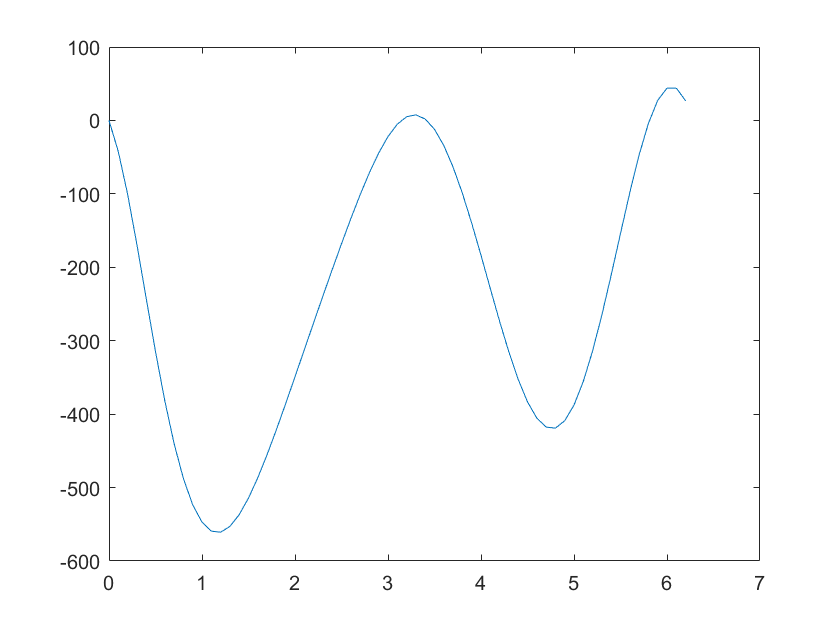

plot(0:0.1:(2*pi),tau)

p = (2*pi*ff)*(tau)/1000

p =          0   -1.3305   -3.1553   -5.3102   -7.6123   -9.8885  -11.9953  -13.8280  -15.3215  -16.4437  -17.1891  -17.5713  -17.6185  -17.3685  -16.8653  -16.1556  -15.2855  -14.2977  -13.2294  -12.1112  -10.9662   -9.8113   -8.6575   -7.5127   -6.3832   -5.2767   -4.2044   -3.1828   -2.2355   -1.3922   -0.6879   -0.1596    0.1582    0.2371    0.0594   -0.3801   -1.0728   -1.9966   -3.1180   -4.3931   -5.7700   -7.1904   -8.5920   -9.9099  -11.0798  -12.0403  -12.7361  -13.1218  -13.1649  -12.8490


plot(0:0.1:(2*pi),abs(p))
p_max = (2*pi*ff)*max(abs(tau))/1000   

p_max = 17.6185

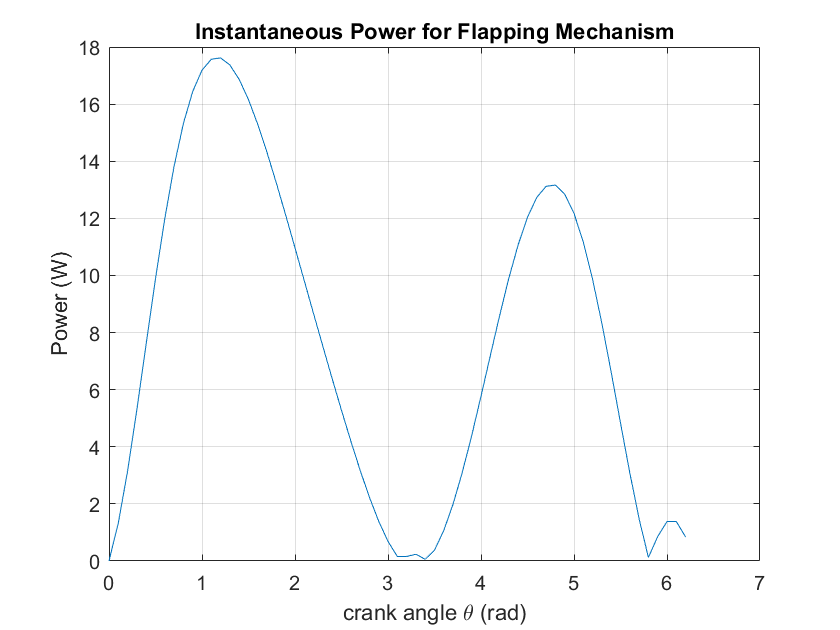

title('Instantaneous Power for Flapping Mechanism')
xlabel('crank angle \theta (rad)')
ylabel('Power (W)')
grid on

p_abs = abs(p)

p_abs =          0    1.3305    3.1553    5.3102    7.6123    9.8885   11.9953   13.8280   15.3215   16.4437   17.1891   17.5713   17.6185   17.3685   16.8653   16.1556   15.2855   14.2977   13.2294   12.1112   10.9662    9.8113    8.6575    7.5127    6.3832    5.2767    4.2044    3.1828    2.2355    1.3922    0.6879    0.1596    0.1582    0.2371    0.0594    0.3801    1.0728    1.9966    3.1180    4.3931    5.7700    7.1904    8.5920    9.9099   11.0798   12.0403   12.7361   13.1218   13.1649   12.8490


mean(p_abs)

ans = 7.6674